# Laborator 2

## Problema 1

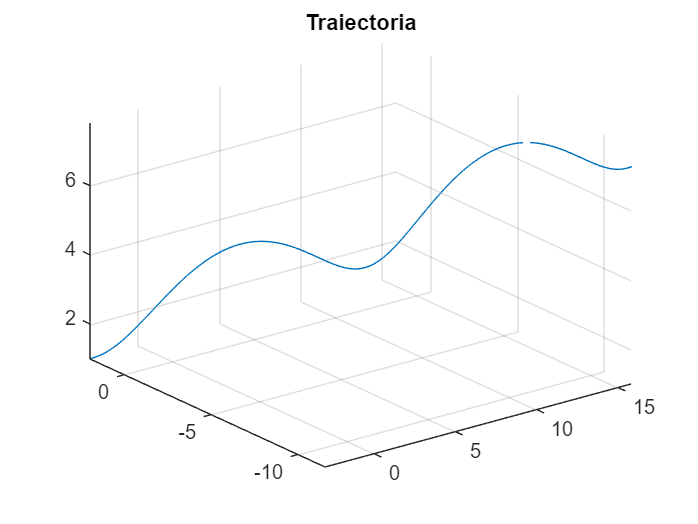

syms t;

v_0x=2;
v_0y=-3;
v_0z=1;

ax=2*sin(2*t);
ay=exp(1).^(-t);
az=4*cos(2*t);

t_0=0;
t_f=2*pi;

vx=int(ax,t_0,t)+v_0x;
vy=int(ay,t_0,t)+v_0y;
vz=int(az,t_0,t)+v_0z;

r_0x=-3;
r_0y=2;
r_0z=1;

x=int(vx,t_0,t)+r_0x;
y=int(vy,t_0,t)+r_0y;
z=int(vz,t_0,t)+r_0z;

v=sqrt(vx.^2+vy.^2+vz.^2);
a=sqrt(ax.^2+ay.^2+az.^2);

V=[vx vy vz];
A=[ax ay az];
VxA=cross(V,A);

vxa=sqrt(VxA(1).^2+VxA(2).^2+VxA(3).^2);

R=(v.^3)./vxa;

figure(1)
fplot3(x,y,z,[t_0,t_f])
title('Traiectoria')

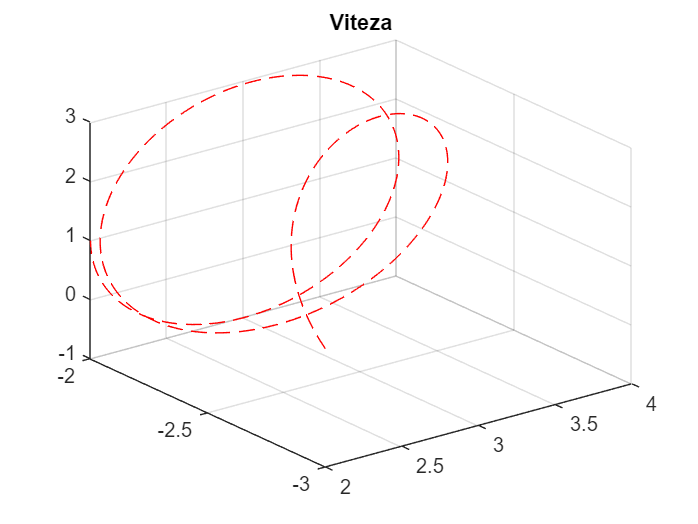


figure(2)
fplot3(vx,vy,vz,[t_0,t_f],'r--')
title('Viteza')

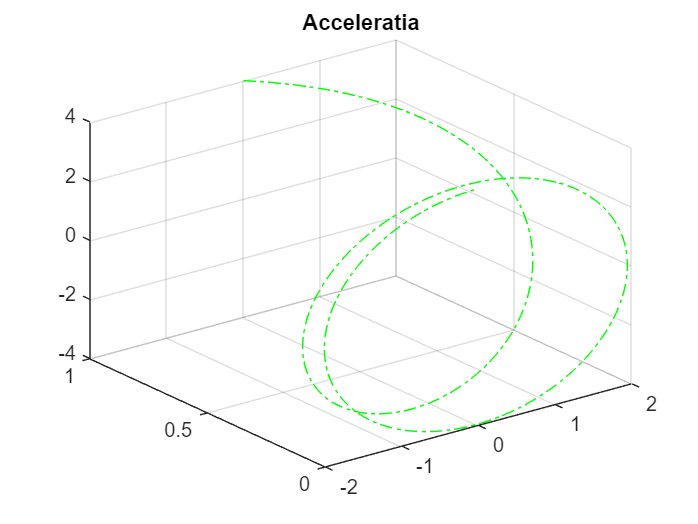


figure(3)
fplot3(ax,ay,az,[t_0,t_f],'g-.')
title('Acceleratia')

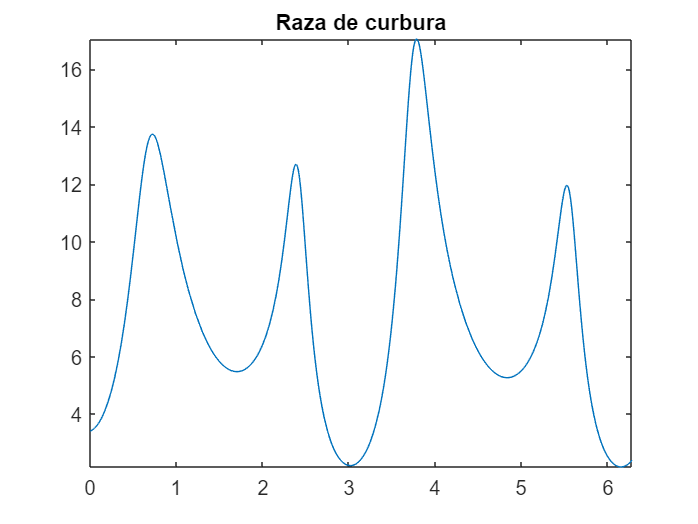


figure(4)
fplot(R,[t_0,t_f])
title('Raza de curbura')

## Problema 2

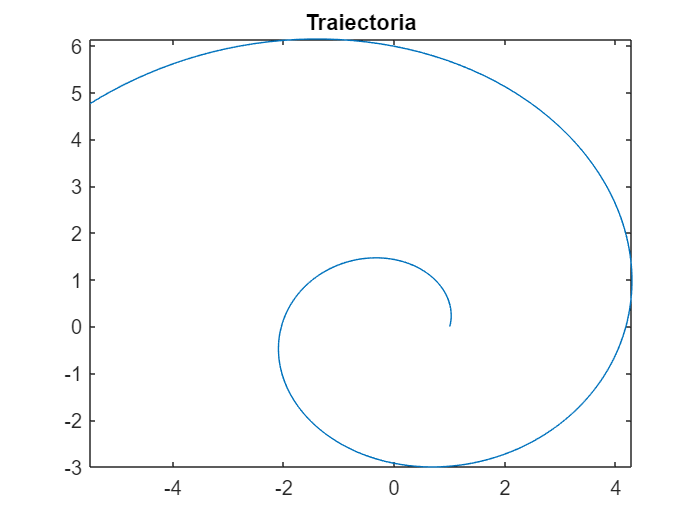

syms t;

t_0=0;
t_f=pi;

c=9;
c_r=2;
c_theta=sqrt(c^2-c_r^2);

P=[1 0];

r=int(c_r,t_0,t)+P(1);
theta=int((c_theta./r),t_0,t);

x=r.*cos(theta);
y=r.*sin(theta);

figure(1)
fplot(x,y,[t_0,t_f])
title("Traiectoria")

## Problema 3

### a)

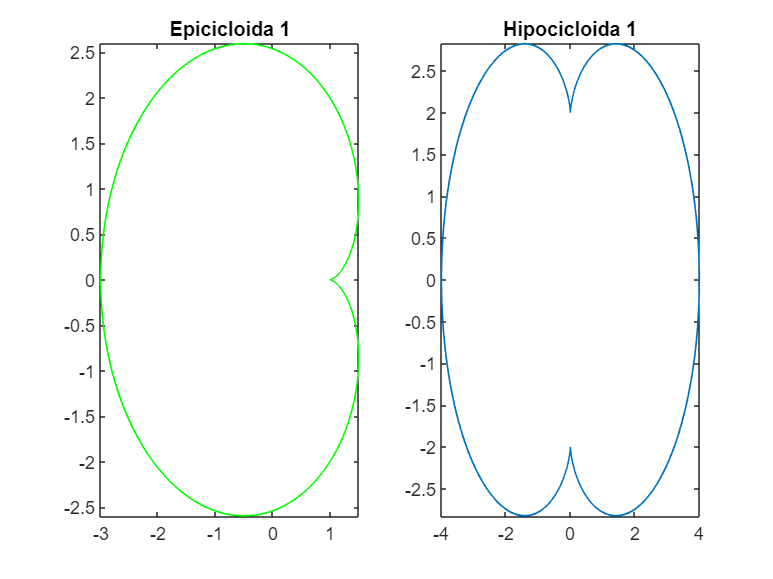

syms t;

t_0=0;
t_f=20*pi;

r=1;
ke1=1;
kh1=4;

xe1=r*(ke1+1)*cos(t)-r*cos((ke1+1).*t);
ye1=r*(ke1+1)*sin(t)-r*sin((ke1+1).*t);

xh1=r*(kh1-1)*cos(t)+r*cos((kh1-1).*t);
yh1=r*(kh1-1)*sin(t)+r*sin((kh1-1).*t);


figure(1)
axis square
subplot(1,2,1);
fplot(xe1,ye1,[t_0,t_f], 'g')
title('Epicicloida 1')

subplot(1,2,2);
fplot(xh1,yh1,[t_0,t_f])
title('Hipocicloida 1')

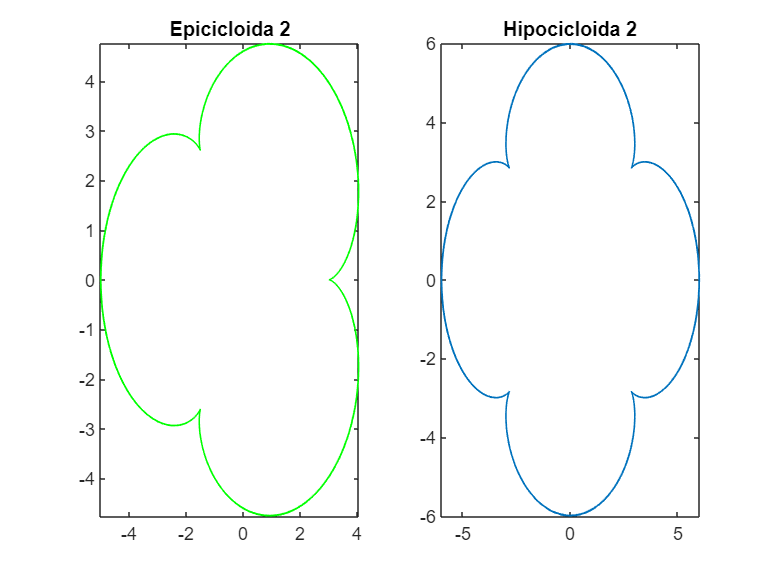


ke2=3;
kh2=6;

xe2=r*(ke2+1)*cos(t)-r*cos((ke2+1).*t);
ye2=r*(ke2+1)*sin(t)-r*sin((ke2+1).*t);

xh2=r*(kh2-1)*cos(t)+r*cos((kh2-1).*t);
yh2=r*(kh2-1)*sin(t)+r*sin((kh2-1).*t);


figure(2)
subplot(1,2,1);
fplot(xe2,ye2,[t_0,t_f], 'g')
title('Epicicloida 2')

subplot(1,2,2);
fplot(xh2,yh2,[t_0,t_f])
title('Hipocicloida 2')

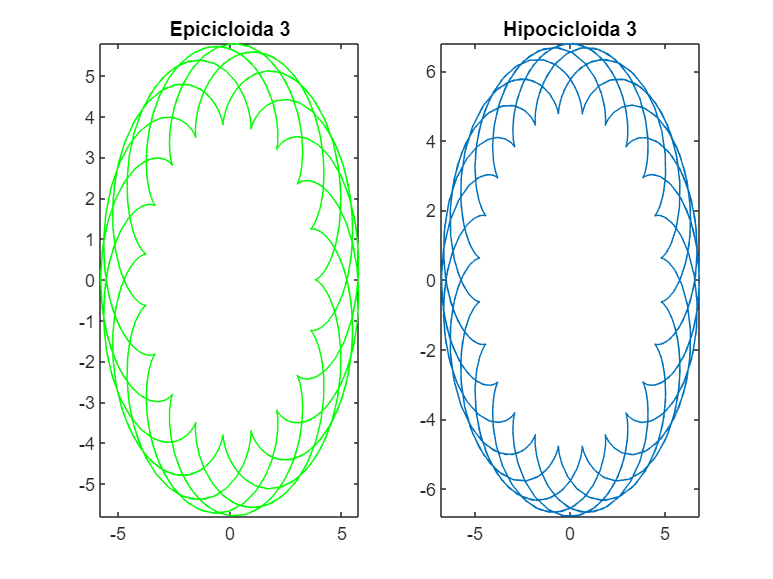


ke3=3.8;
kh3=6.8;

xe3=r*(ke3+1)*cos(t)-r*cos((ke3+1).*t);
ye3=r*(ke3+1)*sin(t)-r*sin((ke3+1).*t);

xh3=r*(kh3-1)*cos(t)+r*cos((kh3-1).*t);
yh3=r*(kh3-1)*sin(t)+r*sin((kh3-1).*t);


figure(3)
subplot(1,2,1);
fplot(xe3,ye3,[t_0,t_f], 'g')
title('Epicicloida 3')

subplot(1,2,2);
fplot(xh3,yh3,[t_0,t_f])
title('Hipocicloida 3')

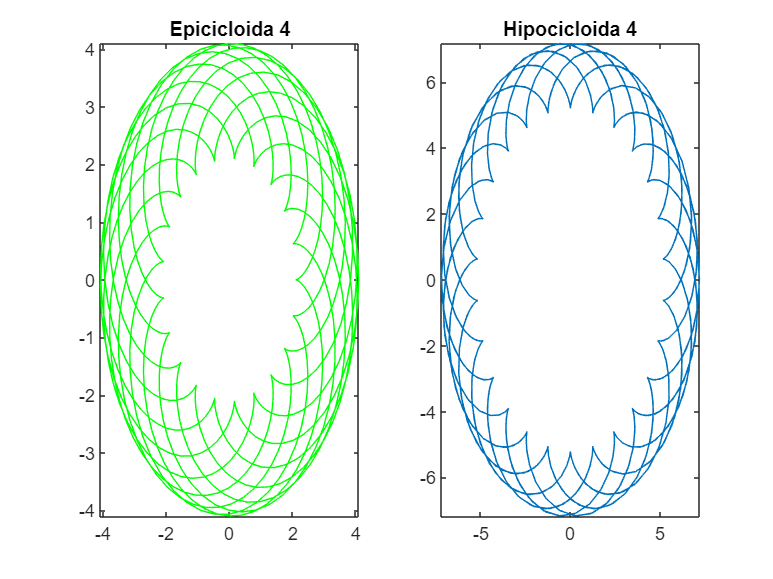


ke4=2.1;
kh4=7.2;

xe4=r*(ke4+1)*cos(t)-r*cos((ke4+1).*t);
ye4=r*(ke4+1)*sin(t)-r*sin((ke4+1).*t);

xh4=r*(kh4-1)*cos(t)+r*cos((kh4-1).*t);
yh4=r*(kh4-1)*sin(t)+r*sin((kh4-1).*t);


figure(4)
subplot(1,2,1);
fplot(xe4,ye4,[t_0,t_f], 'g')
title('Epicicloida 4')

subplot(1,2,2);
fplot(xh4,yh4,[t_0,t_f])
title('Hipocicloida 4')